# Análise da série exponencial de Fourier

clear;
clc;
close all;



$$\frac{\tau}{T_0} \frac{sin(n\omega_0 \tau /2)}{n \omega_0 \tau /2}$$


Fourier = @(n, wo, tau, To)  tau/To.* sinc(n*wo*tau/(2*pi));

N = 10;         % número de projeções
n = [-10:1:10]; % valores de n para substituição de Fourier
To = 3e-6;      % período do sinal
wo = 2*pi/To;   % frequência do sinal
tau = 2e-6;     % largura do pulso
w   = n*wo;     % frequência angular
freq= w/(2*pi)  % frequência em Hz

freq = 	1.0e+06 *

   -3.3333   -3.0000   -2.6667   -2.3333   -2.0000   -1.6667   -1.3333   -1.0000   -0.6667   -0.3333         0    0.3333    0.6667    1.0000    1.3333    1.6667    2.0000    2.3333    2.6667    3.0000    3.3333



Dn = Fourier(n, wo, tau, To)

Dn =     0.0276   -0.0000   -0.0345    0.0394   -0.0000   -0.0551    0.0689   -0.0000   -0.1378    0.2757    0.6667    0.2757   -0.1378   -0.0000    0.0689   -0.0551   -0.0000    0.0394   -0.0345   -0.0000    0.0276


## Visualização dos coeficientes de Fourier

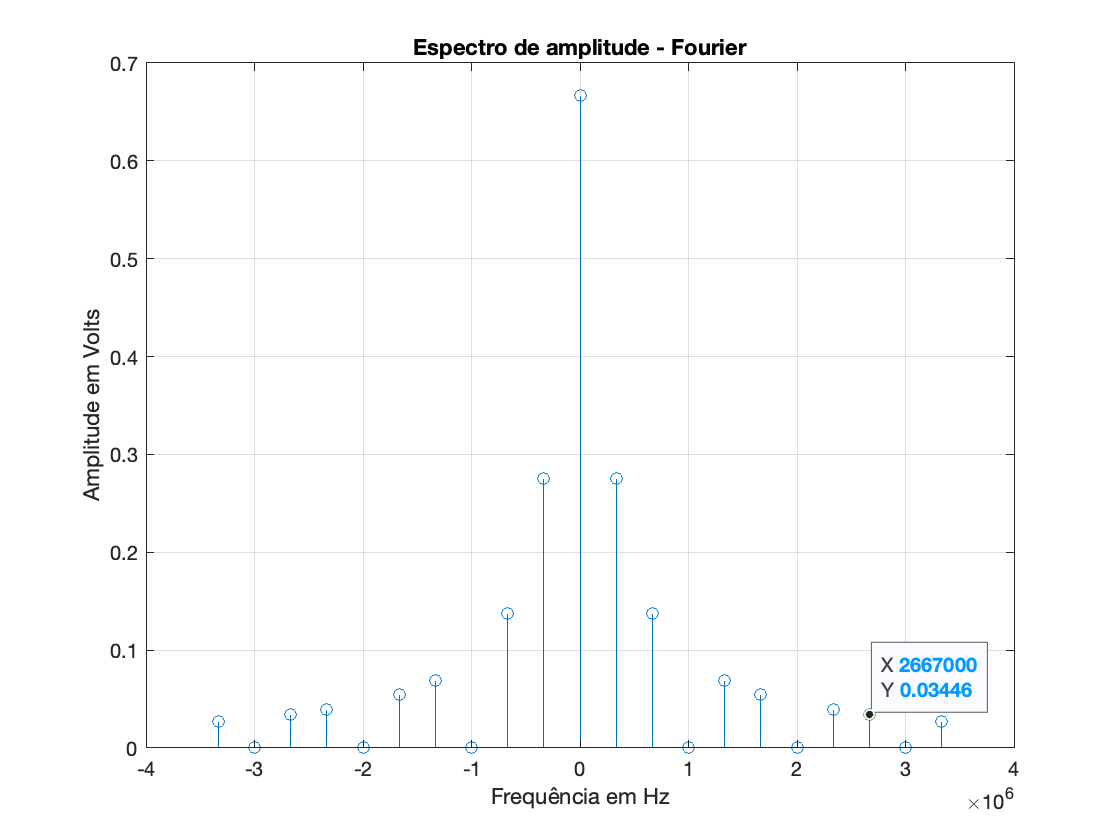


figure()
stem(freq,abs(Dn));grid;
xlabel('Frequência em Hz')
ylabel('Amplitude em Volts')
title('Espectro de amplitude - Fourier')